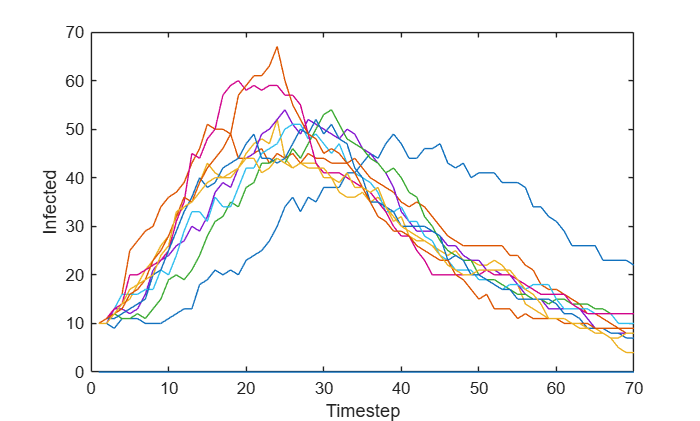

function [Sh, Ih, Rh] = simulate_absir(M, Iv0, T, infection_rate, recovery_rate)
% Simulate agent-based transmission model. Uses a graph to represent social
% connectivity between agents.
% 
% Note: You may find it helpful to summarize the state history matrices via
% summation. For instance sum(Ih, 1) will return the total number of
% infected persons at each timestep in the simulation.
%
% Inputs
%   M (square matrix): Adjacency matrix
%   Iv0 (column vector): Initial infection state
%   T (integer): Number of timesteps to simulate
%   infection_rate (float): Infection rate (probabilistic)
%   recovery_rate (float): Recovery rate (probabilistic)
% 
% Returns
%   Sh (matrix): Susceptible state history
%   Ih (matrix): Infected state history
%   Rh (matrix): Recovered state history

% Setup
dim = length(Iv0);  % Dimensions of initial state
Ih = zeros(dim, T); % Infection history
Ih(:, 1) = Iv0; % Record the initial state to infection history
Rh = zeros(dim, T); % Recovery history

% Construct an "action" helper function
    function [I, R] = action(I, R)
        % Compute infection probabilities based on the social graph
        v_eff = infection_rate * M * I;
        v_pr = v_eff ./ (1 + v_eff);

        % Draw random values
        v_infect = rand(dim, 1) <= v_pr;
        v_recover = rand(dim, 1) <= recovery_rate;

        % Infect non-recovered individuals
        I = I | v_infect & (~R);
        % Recover infected individuals
        R = R | (I & v_recover);
        I = I & (~R);
    end

% Run simulation
for i = 2:T
    [Ih(:, i), Rh(:, i)] = action(Ih(:, i-1), Rh(:, i-1));
end

% Compute susceptible history
Sh = ones(dim, T) - Ih - Rh;
end


function strength = distancetostrength(d)
strength = exp(-d/50); 
%strength = 1/(1+d^2);
end 

function M_res = make_adj_pods(n_per_pod, n_pods, dBlock)
% Construct an adjacency matrix for a "podding" scenario
%
% Usage
%   M_res = make_adj_pods(n_per_pod, n_pods, infectivity)
%
% Arguments
%   n_per_pod  = number of persons per "pod"
%   n_pods     = total number of pods; total population = n_per_pod * n_pods
%   pod_effect = relative infectivity within pods; should be infectivity > 1
%
% Returns
%   M_res = adjacency matrix for desired graph
n_total = n_per_pod * n_pods;

% Create the "base matrix" with weak connections between all persons
M_res =  distancetostrength(dBlock)* (ones(n_total, n_total) - eye(n_total));

% Add the pod structure
for i = 1:n_pods
    % Determine the slicing indices
    i0 = (i - 1) * n_per_pod + 1; ie = i0 + n_per_pod - 1;
    % Assign strong in-pod weights
    M_res(i0:ie, i0:ie) = 10 * M_res(i0:ie, i0:ie);
end

end

% x = zeros(120,1);
% for i = 1:120
%     prob = rand * 12;
%     if prob > 1
%         x(i) = 0;
%     end 
%     if prob < 1
%         x(i) = 1;
%     end 
% end 

initial_state = zeros(120, 1);
initial_state(1:10) = 1;



t_end = 70;
infection_rate = 0.005;
recovery_rate = 0.05;

% number of different distances
num_steps = 50;

% range of possible distances
min_distance = 50; max_distance = 200;
num_trials = 10;

% array of possible distances
distance_vals = linspace(min_distance, max_distance, num_steps);
I_mean = zeros(num_steps, t_end);

for k = 1:num_steps
    adj_matrix = make_adj_pods(20, 6, distance_vals(k));
    for p = 1:num_trials
        [~, Ih, ~] = simulate_absir(adj_matrix, initial_state, t_end, infection_rate, recovery_rate);
        I_mean(k,:) = I_mean(k,:) + sum(Ih, 1) / num_trials;
    end
end
figure
plot(1:t_end, I_temp')
xlabel('Timestep'); ylabel('Infected')

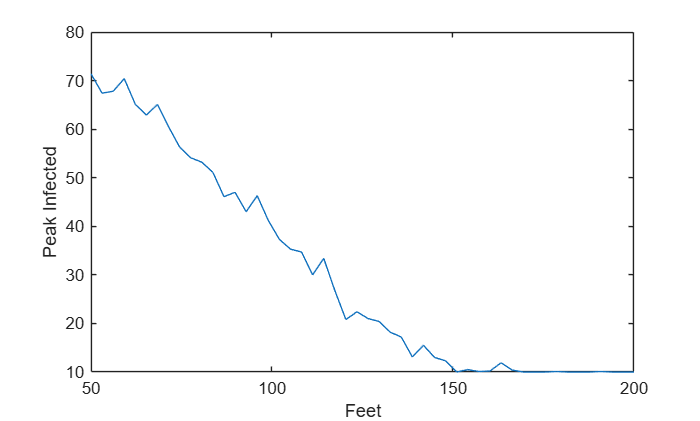

peaks = max(I_mean, [], 2);

figure
plot(distance_vals, peaks)
xlabel('Feet'); ylabel('Peak Infected')